clear; clc;
cvx_clear;

addpath './../classes'

steps = 21;

theta_vec = linspace(0, pi/2, steps);
fidelities = zeros(1, steps);

syms theta
assume( theta, "real")

Ry = [ cos(theta)  -sin(theta);
       sin(theta)   cos(theta) ] 

$$Ry = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$


psi0 = [1;0]

psi0 =      1
     0


rho0_in = psi0*psi0'

rho0_in =      1     0
     0     0


psi1 = [0;1]

psi1 =      0
     1


rho1_in = psi1*psi1'

rho1_in =      0     0
     0     1



for k = 1:steps
    phi = theta_vec(k);
    U = double( subs( Ry, theta, phi ) );
    psiA = U*psi0;
    rhoA_in = psiA*psiA';

    psiB = U*psi1;
    rhoB_in = psiB*psiB';

    states = [ psi0, psi1, psiA, psiB ];

    sdp = SDP_Symmetric_1to2_Cloner(states);
    [optimal_fidelity, J] = sdp.solvePrimal();
    [dual_optimum, Y]   = sdp.solveDual();

    K = Utils.getKrausOperators(J,1,2);
    K1 = K{1};
    K2 = K{2};

    rho0_out = K1*rho0_in*K1' + K2*rho0_in*K2';
    rho0_out_A = PartialTrace( rho0_out, [2],[2,2]);
    rho0_out_B = PartialTrace( rho0_out, [1],[2,2]);
    F0_A = trace( rho0_in*rho0_out_A );
    F0_B = trace( rho0_in*rho0_out_B );

    rho1_out = K1*rho1_in*K1' + K2*rho1_in*K2';
    rho1_out_A = PartialTrace( rho1_out, [2],[2,2]);
    rho1_out_B = PartialTrace( rho1_out, [1],[2,2]);
    F1_A = trace( rho1_in*rho1_out_A );
    F1_B = trace( rho1_in*rho1_out_B );

    rhoA_out = K1*rhoA_in*K1' + K2*rhoA_in*K2';
    rhoA_out_A = PartialTrace( rhoA_out, [2],[2,2]);
    rhoA_out_B = PartialTrace( rhoA_out, [1],[2,2]);
    FA_A = trace( rhoA_in*rhoA_out_A );
    FA_B = trace( rhoA_in*rhoA_out_B );

    rhoB_out = K1*rhoB_in*K1' + K2*rhoB_in*K2';
    rhoB_out_A = PartialTrace( rhoB_out, [2],[2,2]);
    rhoB_out_B = PartialTrace( rhoB_out, [1],[2,2]);
    FB_A = trace( rhoB_in*rhoB_out_A );
    FB_B = trace( rhoB_in*rhoB_out_B );

    f = (1 + sqrt( sin(phi)^4 + cos(phi)^4  ))/2;
    fprintf("Compare Function  = %6.4f, F_A = %6.4f, F_opt = %6.4f \n", f, FB_A, optimal_fidelity );
    fprintf("Fideliteis: %6.4f, %6.4f, %6.4f, %6.4f \n", F0_A, F1_A, FA_A, FB_A );
    fprintf("Fideliteis: %6.4f, %6.4f, %6.4f, %6.4f \n", F0_B, F1_B, FA_B, FB_B );
    fprintf("------------------------------------------\n")
    fidelities(k) = F0_A;
end

Compare Function  = 1.0000, F_A = 1.0000, F_opt = 1.0000 


Fideliteis: 1.0000, 1.0000, 1.0000, 1.0000 


Fideliteis: 1.0000, 1.0000, 1.0000, 1.0000 


------------------------------------------


Compare Function  = 0.9969, F_A = 0.9969, F_opt = 0.9969 


Fideliteis: 0.9969, 0.9969, 0.9969, 0.9969 


Fideliteis: 0.9969, 0.9969, 0.9969, 0.9969 


------------------------------------------


Compare Function  = 0.9879, F_A = 0.9879, F_opt = 0.9879 


Fideliteis: 0.9879, 0.9879, 0.9879, 0.9879 


Fideliteis: 0.9879, 0.9879, 0.9879, 0.9879 


------------------------------------------


Compare Function  = 0.9735, F_A = 0.9735, F_opt = 0.9735 


Fideliteis: 0.9735, 0.9735, 0.9735, 0.9735 


Fideliteis: 0.9735, 0.9735, 0.9735, 0.9735 


------------------------------------------


Compare Function  = 0.9548, F_A = 0.9548, F_opt = 0.9548 


Fideliteis: 0.9548, 0.9548, 0.9548, 0.9548 


Fideliteis: 0.9548, 0.9548, 0.9548, 0.9548 


------------------------------------------


Compare Function  = 0.9330, F_A = 0.9330, F_opt = 0.9330 


Fideliteis: 0.9330, 0.9330, 0.9330, 0.9330 


Fideliteis: 0.9330, 0.9330, 0.9330, 0.9330 


------------------------------------------


Compare Function  = 0.9101, F_A = 0.9101, F_opt = 0.9101 


Fideliteis: 0.9101, 0.9101, 0.9101, 0.9101 


Fideliteis: 0.9101, 0.9101, 0.9101, 0.9101 


------------------------------------------


Compare Function  = 0.8883, F_A = 0.8883, F_opt = 0.8883 


Fideliteis: 0.8883, 0.8883, 0.8883, 0.8883 


Fideliteis: 0.8883, 0.8883, 0.8883, 0.8883 


------------------------------------------


Compare Function  = 0.8700, F_A = 0.8700, F_opt = 0.8700 


Fideliteis: 0.8700, 0.8700, 0.8700, 0.8700 


Fideliteis: 0.8700, 0.8700, 0.8700, 0.8700 


------------------------------------------


Compare Function  = 0.8579, F_A = 0.8579, F_opt = 0.8579 


Fideliteis: 0.8579, 0.8579, 0.8579, 0.8579 


Fideliteis: 0.8579, 0.8579, 0.8579, 0.8579 


------------------------------------------


Compare Function  = 0.8536, F_A = 0.8536, F_opt = 0.8536 


Fideliteis: 0.8536, 0.8536, 0.8536, 0.8536 


Fideliteis: 0.8536, 0.8536, 0.8536, 0.8536 


------------------------------------------


Compare Function  = 0.8579, F_A = 0.8579, F_opt = 0.8579 


Fideliteis: 0.8579, 0.8579, 0.8579, 0.8579 


Fideliteis: 0.8579, 0.8579, 0.8579, 0.8579 


------------------------------------------


Compare Function  = 0.8700, F_A = 0.8700, F_opt = 0.8700 


Fideliteis: 0.8700, 0.8700, 0.8700, 0.8700 


Fideliteis: 0.8700, 0.8700, 0.8700, 0.8700 


------------------------------------------


Compare Function  = 0.8883, F_A = 0.8883, F_opt = 0.8883 


Fideliteis: 0.8883, 0.8883, 0.8883, 0.8883 


Fideliteis: 0.8883, 0.8883, 0.8883, 0.8883 


------------------------------------------


Compare Function  = 0.9101, F_A = 0.9101, F_opt = 0.9101 


Fideliteis: 0.9101, 0.9101, 0.9101, 0.9101 


Fideliteis: 0.9101, 0.9101, 0.9101, 0.9101 


------------------------------------------


Compare Function  = 0.9330, F_A = 0.9330, F_opt = 0.9330 


Fideliteis: 0.9330, 0.9330, 0.9330, 0.9330 


Fideliteis: 0.9330, 0.9330, 0.9330, 0.9330 


------------------------------------------


Compare Function  = 0.9548, F_A = 0.9548, F_opt = 0.9548 


Fideliteis: 0.9548, 0.9548, 0.9548, 0.9548 


Fideliteis: 0.9548, 0.9548, 0.9548, 0.9548 


------------------------------------------


Compare Function  = 0.9735, F_A = 0.9735, F_opt = 0.9735 


Fideliteis: 0.9735, 0.9735, 0.9735, 0.9735 


Fideliteis: 0.9735, 0.9735, 0.9735, 0.9735 


------------------------------------------


Compare Function  = 0.9879, F_A = 0.9879, F_opt = 0.9879 


Fideliteis: 0.9879, 0.9879, 0.9879, 0.9879 


Fideliteis: 0.9879, 0.9879, 0.9879, 0.9879 


------------------------------------------


Compare Function  = 0.9969, F_A = 0.9969, F_opt = 0.9969 


Fideliteis: 0.9969, 0.9969, 0.9969, 0.9969 


Fideliteis: 0.9969, 0.9969, 0.9969, 0.9969 


------------------------------------------


Compare Function  = 1.0000, F_A = 1.0000, F_opt = 1.0000 


Fideliteis: 1.0000, 1.0000, 1.0000, 1.0000 


Fideliteis: 1.0000, 1.0000, 1.0000, 1.0000 


------------------------------------------


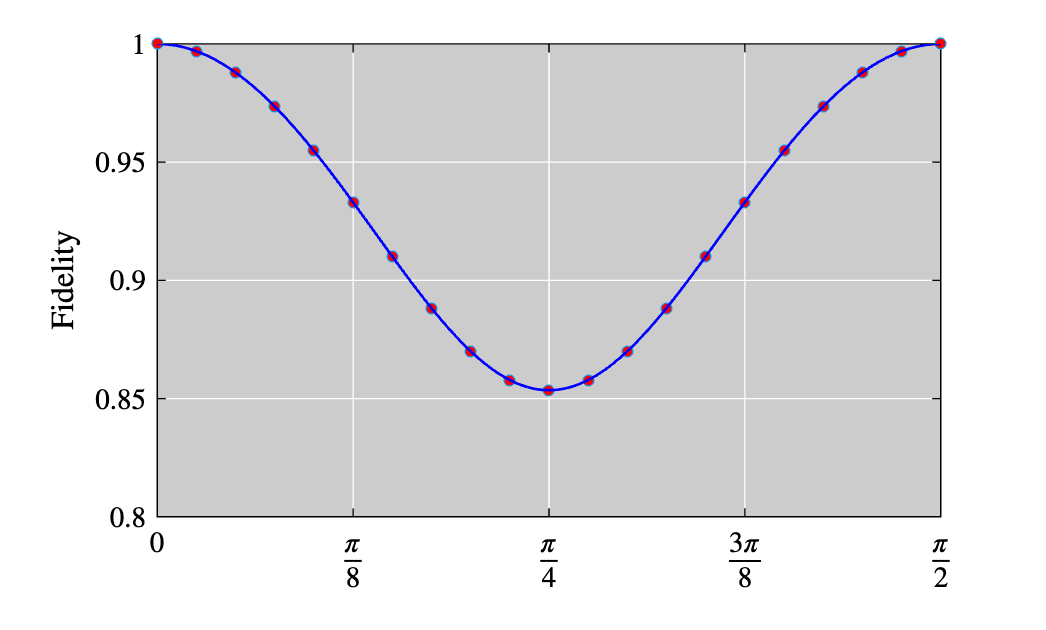

% Visualization using LaTeX and a white background
figure('Color', 'w'); % Set outer background to white

% 1. Plot the available data points
% 'o' creates markers; 'MarkerSize' and 'MarkerFaceColor' improve visibility
plot(theta_vec, fidelities, 'o', 'MarkerSize', 4, 'MarkerFaceColor', 'r', 'DisplayName', 'Data points'); 
hold on;

% 2. Define and plot the theoretical function
% We use theta_vec for a smooth curve (or a finer grid if needed)
theta_func = linspace(0, pi/2, 300);
f_theory = (1 + sqrt(sin(theta_func).^4 + cos(theta_func).^4)) / 2;
plot(theta_func, f_theory, 'b-', 'LineWidth', 1, 'DisplayName', '$\frac{1 + \sqrt{\sin^4(\theta) + \cos^4(\theta)}}{2}$');

% Set axis limits
ylim([0.8, 1.0]);
xlim([0.0, pi/2]);

% Set the plot background to light gray
set(gca, 'Color', [0.8, 0.8, 0.8]);

% Grid and axis labels
grid on;
set(gca, 'GridColor', 'w', 'GridAlpha', 1); 
% xlabel('$\theta$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
ylabel('Fidelity', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 11,'FontName','Arial');

% Use LaTeX for axis tick labels
xticks([0 pi/8 pi/4 3*pi/8 pi/2]); % Ticks adapted to xlim [0, pi/2]
xticklabels({'$0$', '$\frac{\pi}{8}$', '$\frac{\pi}{4}$', '$\frac{3\pi}{8}$', '$\frac{\pi}{2}$'});
set(gca, 'XColor', [0 0 0], 'YColor', [0 0 0]); 
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11, 'FontName','Arial');

% --- MORE OUTER SPACING ---
set(gca, 'Units', 'normalized');
set(gca, 'OuterPosition', [0, 0, 1, 1]); 
set(gca, 'InnerPosition', [0.15, 0.18, 0.75, 0.75]); % Slightly adjusted for better visibility

% Export figure
exportgraphics(gcf, './figures/FidelityTwoNonOrthogonalStates.jpg', 'Resolution', 300);